# 図の設定練習(修正例)

折れ線グラフを適切に設定しましょう．

clear;clc;close all;

気象庁のWebサイトから入手した2023年の名古屋の気温に関するデータを読み込む．

参考：[https://www.data.jma.go.jp/obd/stats/etrn/view/monthly_s1.php?prec_no=51&block_no=47636&year=2023&month=&day=&view=](https://www.data.jma.go.jp/obd/stats/etrn/view/monthly_s1.php?prec_no=51&block_no=47636&year=2023&month=&day=&view=)

tbl=readtable("data_nagoya2023.xlsx", ...
    'VariableNamingRule','preserve');
figure;hold on;grid on;
set(gca,'fontname','メイリオ','fontsize',12);
d=datetime(tbl.("年"),tbl.("月"),1);
plot(d,tbl.("平均気温"),'o-','LineWidth',2);
plot(d,tbl.("平均日最高"),'*--','LineWidth',2);
plot(d,tbl.("平均日最低"),'.:','LineWidth',2);
set(gca,'xtick',datetime(2023,1:12,1),'xticklabelrotation',90);
ylabel('気温[度]');
title('名古屋の気温(2023年)');
legend({'平均気温','平均日最高','平均日最低'},'Location','northoutside','Orientation','horizontal');
xlim([datetime(2022,12,15),datetime(2023,12,15)]);
exportgraphics(gcf,'fig_figureSettingExercise_A.pdf');

TIPs: get(gca)で図の設定を確認できます．

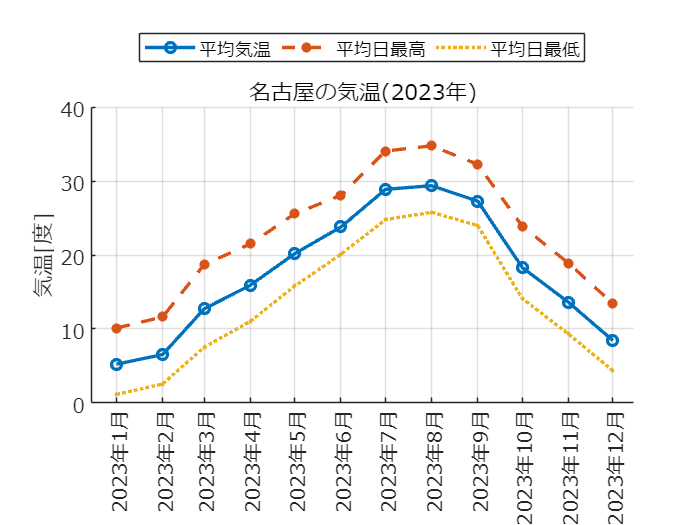

                        ALim: [0 1]
                    ALimMode: 'auto'
                  AlphaScale: 'linear'
                    Alphamap: [0 0.0159 0.0317 0.0476 0.0635 0.0794 0.0952 0.1111 0.1270 0.1429 0.1587 0.1746 0.1905 0.2063 0.2222 0.2381 0.2540 0.2698 0.2857 0.3016 0.3175 0.3333 0.3492 0.3651 0.3810 0.3968 0.4127 0.4286 0.4444 0.4603 … ] (1×64 double)
           AmbientLightColor: [1 1 1]
                BeingDeleted: off
                         Box: off
                    BoxStyle: 'back'
                  BusyAction: 'queue'
               ButtonDownFcn: ''
                        CLim: [0 1]
                    CLimMode: 'auto'
              CameraPosition: [165.5000 20 17.3205]
          CameraPositionMode: 'auto'
                CameraTarget: [165.5000 20 0]
            CameraTargetMode: 'auto'
              CameraUpVector: [0 1 0]
          CameraUpVectorMode: 'auto'
             CameraViewAngle: 6.6086
         CameraViewAngleMode: 'auto'
                    Childr

get(gca)